
clear;
clc;
format long;
disp(strcat("report Generated on: ",string(datestr(now))))

report Generated on: 22-Apr-2023 03:38:05




SingleAnalysis = false;

### **Clean Everything Before Start**



% Check if running in batch mode
tempMatPath = fullfile(pwd, 'temp.mat');
if exist(tempMatPath, 'file')
    if (SingleAnalysis==true)
    delete(tempMatPath);
    batchMode = false;
    else
    % Load variables from the temporary MAT-file (batch mode)
    load(tempMatPath, 'batchMode', 'bi', 'dirNames', 'dirPaths', 'dirTest', 'dirPath', 'allDataFolderPath', 'scriptPath');
    end
else
    % Set variables for standalone mode (You can customize this part as needed)
    batchMode = false;
    % Define or load the necessary variables when running in standalone mode
    % For example, you can set dirTest, dirPath, etc. according to your needs
%     dirTest = 'YourStandAloneDirTest';
%     dirPath = 'YourStandAloneDirPath';
end



%for Scalogram Analysis
step_window = 10;
window = 30;
 excGradTreshhold = 0.05;

### **Select the Specific Log Folder**

The folder Contains 5 files

- PreFlight CAT Test Image

- PreFlight CAT Test CSV

- PostFlight CAT Test Image

- PostFlight CAT Test CSV

- Trial Data .mat File

%select directory
 if ~exist('dirPath','var')
dirPath = uigetdir("logs\firstSeries\","Select the Log Directory...");
else 
   % dirPath = dirTest;
 end
[~, last_folder_name, ~] = fileparts(dirPath); 
listFiles = dir(dirPath);
fileNames = {listFiles.name};
% create a logical index of files that are not hidden and not directories
validFiles = ~ismember(fileNames,{'.','..'}) & ~[listFiles.isdir] & ~strncmp('.',fileNames,1);
fileNames = fileNames(validFiles);


preReportcsv = fullfile(dirPath,fileNames(contains(fileNames,"_pre.csv")));
preReportimg = fullfile(dirPath,fileNames(contains(fileNames,"_pre.jp")));

postReportcsv = fullfile(dirPath,fileNames(contains(fileNames,"_post.csv")));
postReportimg = fullfile(dirPath,fileNames(contains(fileNames,"_post.jp")));

matFile = fullfile(dirPath,fileNames(contains(fileNames,".mat")));

%main mat file

load(string(matFile));


%Print Info for the test details
disp("Test Directory");

Test Directory


disp(dirPath);

C:\Users\Alireza\MATLAB Drive\FatigueThesis\logs\firstSeries\Alireza Ghaderi_12-02-2023_04-20-58



disp("Pilot Info");

Pilot Info


disp(pilot);

           name: 'Alireza Ghaderi'
         rating: 'Student'
       beginPVT: 383
         endPVT: 393
     hoursAwake: 2
     selfRating: 8
      taskTitle: 'OIII ILS 29L/KAZ'
           data: [28037×22 table]
    description: {''}
           time: "12-Feb-2023 04:20:57"
        caffein: 'None'



pilot_raw = pilot;

%load preflight CAT Test

preFlightCAT = catImportFun(string(preReportcsv));
disp("Before Test CAT");

Before Test CAT


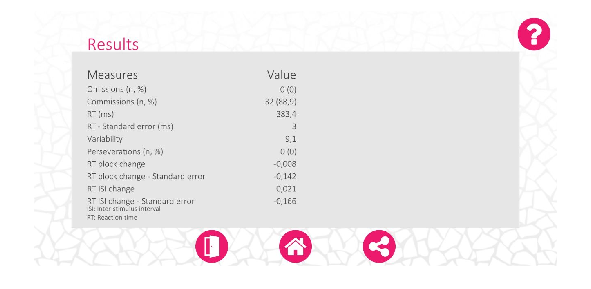

imshow(string(preReportimg));


%load postflight CAT Test

postFlightCAT = catImportFun(string(postReportcsv));
disp("After Test CAT");

After Test CAT


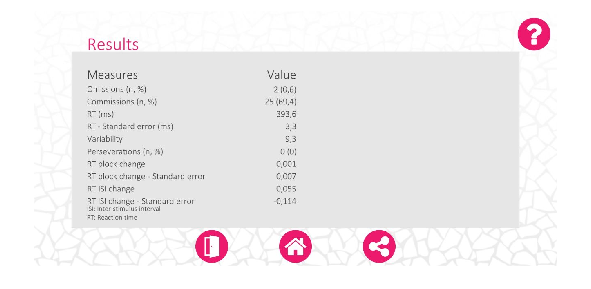

imshow(string(postReportimg));

### **Data Preprocess**

desireFs = 30;
lowPassCutoff_pos = 2;
clipRate_pos = 99.990;
detrendingSmoothingFactor_pos = 0.05;
median_filter_window_pos = 10;
smoothingWindow_pos = 30; %moving average window

lowPassCutoff_vel = 4;
clipRate_vel = 99;
detrendingSmoothingFactor_vel = 0.1;
median_filter_window_vel = 30;
smoothingWindow_vel = 30; %moving average window
stationaryThresholdFactor_vel = 0.25;

%-------------------------------------------------------------------------
% Remove non-unique time from data
[C, ia] = unique(pilot.data.time(:, 1), 'rows');
startPadding = 100;
endPadding = 30;
ia = ia(startPadding:end-endPadding);

% Preallocate the data table with the desired size
nRows = length(ia);
nCols = width(pilot.data);
data = array2table(zeros(nRows, nCols), 'VariableNames', pilot.data.Properties.VariableNames);

% Fill the data table with values from pilot.data
for col = 1:nCols
    temp = pilot.data(ia, col);
    data(:, col) = temp;
end


%resampling
data = signalResample(data,desireFs);


### Iris Preprocessing

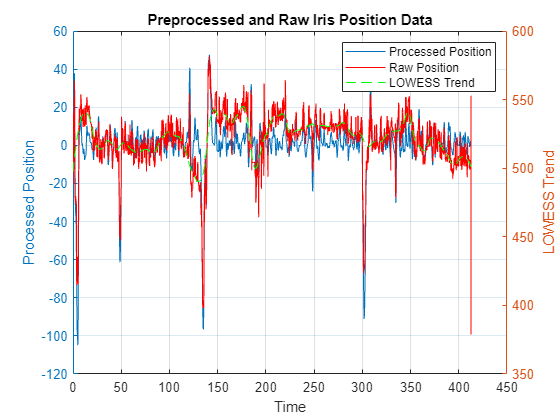

%iris position
time = double(data.time);
irisX_raw = data.irisx;
irisY_raw = data.irisy;


% Preprocess the iris data
[processed_position, position_detrended]  = preprocess_iris_data(irisX_raw, irisY_raw, time, clipRate_pos, lowPassCutoff_pos, smoothingWindow_pos,detrendingSmoothingFactor_pos,median_filter_window_pos);

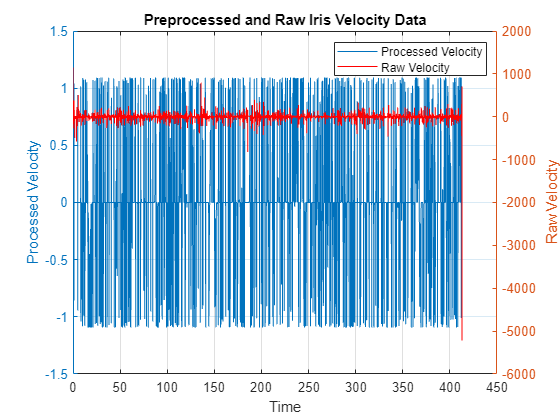


%iris velocity
%preprocess and initilaize iris velocity

processed_velocity = preprocess_iris_velocity(time, position_detrended,clipRate_vel, median_filter_window_vel, lowPassCutoff_vel, smoothingWindow_vel, detrendingSmoothingFactor_vel,stationaryThresholdFactor_vel);

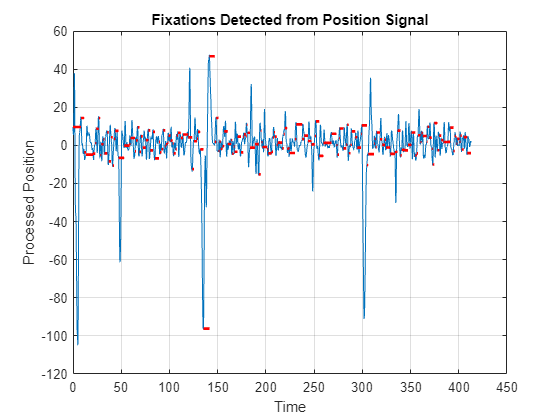

%feature Extraction

positionFeatures = computeIrisFeatures(processed_position, time, desireFs,position_detrended,'pos','trial');

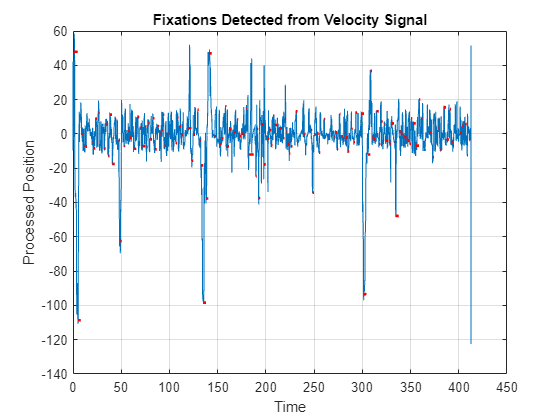

velocityFeatures = computeIrisFeatures(processed_velocity, time, desireFs,position_detrended,'vel','trial');

## Averaging and Displaying Iris Data


%Display Iris Results
%since the values obtained by velocity and position are diffent and yet
%Ihave no idea which one is better, right now I am averaging the two as a
%better measure.



%irisResult Exceedance
irisResult.processedPosition = processed_position;
irisResult.processedVelocity = processed_velocity;
irisResult.positionDetrended = position_detrended;
irisResult.processed_irisX_raw = irisX_raw;
irisResult.processed_irisY_raw = irisY_raw;
irisResult.relative_irisX_raw = data.dxIris;
irisResult.relative_irisX_raw =  data.dyIris;

irisResult.rawPosition = sqrt(irisX_raw.^2 + irisY_raw.^2);


irisResult.trialPositionFeatures = positionFeatures;
irisResult.trialVelocityFeatures = velocityFeatures;


irisResult.meanFixationDuration = mean([irisResult.trialPositionFeatures.meanFixationDuration , irisResult.trialVelocityFeatures.meanFixationDuration]);
irisResult.stdFixationDuration = std([irisResult.trialPositionFeatures.meanFixationDuration , irisResult.trialVelocityFeatures.meanFixationDuration]);
irisResult.numFixation = mean([irisResult.trialPositionFeatures.numFixation , irisResult.trialVelocityFeatures.numFixation]);

disp(irisResult);


%if ~SingleAnalysis

%Creating Figures

        processedPosition: [12385×1 double]
        processedVelocity: [12385×1 double]
        positionDetrended: [12385×1 double]
      processed_irisX_raw: [12385×1 double]
      processed_irisY_raw: [12385×1 double]
       relative_irisX_raw: [12385×1 double]
              rawPosition: [12385×1 double]
    trialPositionFeatures: [1×1 struct]
    trialVelocityFeatures: [1×1 struct]
     meanFixationDuration: 161
      stdFixationDuration: 11.313708498984761
              numFixation: 161



 With Processed Data


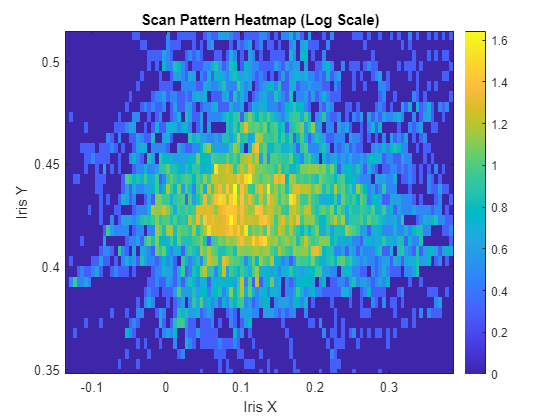

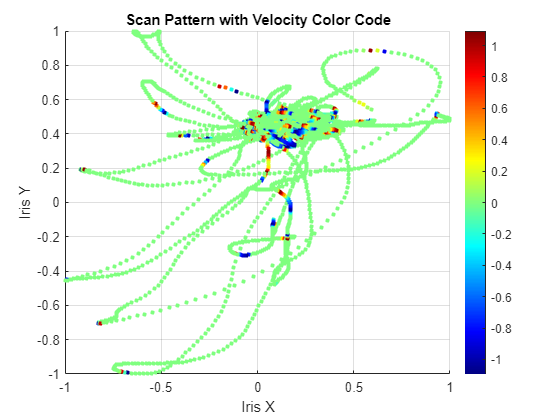

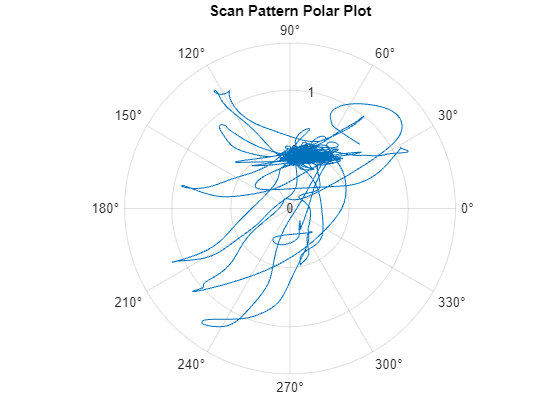

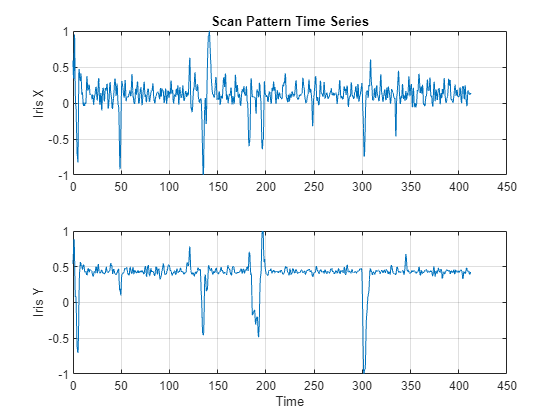

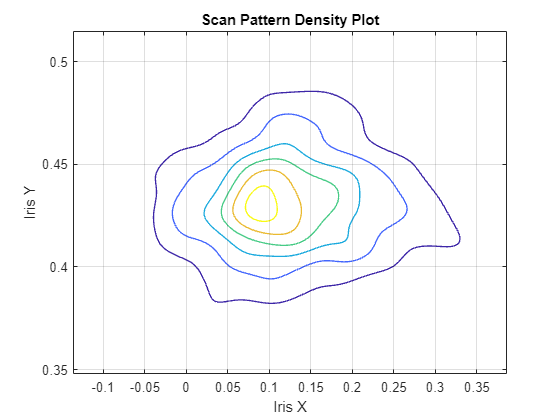

nBinsPlots = 400;
[processed_irisX, processed_irisY] = preprocess_iris_data_separate(irisX_raw, irisY_raw, time, clipRate_pos, lowPassCutoff_pos, smoothingWindow_pos, detrendingSmoothingFactor_pos, median_filter_window_pos);
disp(" With Processed Data");
plot_scan_pattern_visualizations(processed_irisX, processed_irisY, processed_velocity, time, nBinsPlots);

disp(" With Raw Data");
plot_scan_pattern_visualizations(irisX_raw, irisY_raw, processed_velocity, time, nBinsPlots);
%end


%plot Features

 With Raw Data


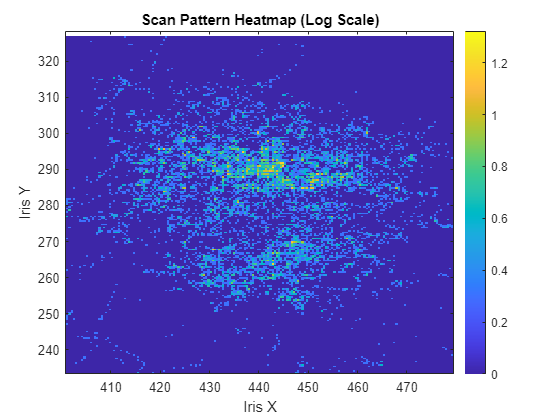

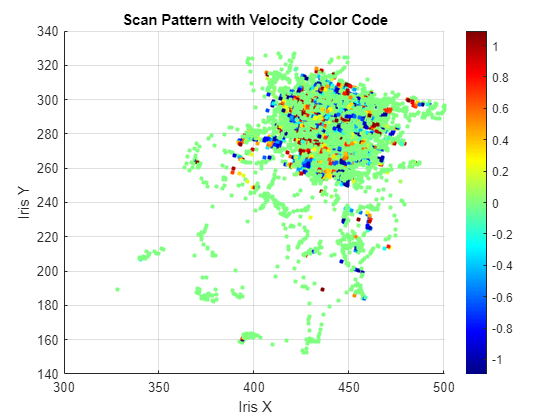

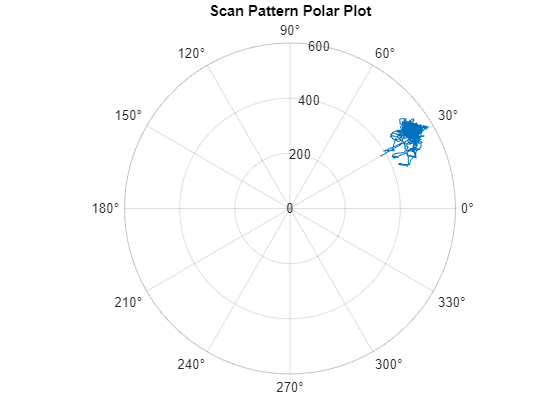

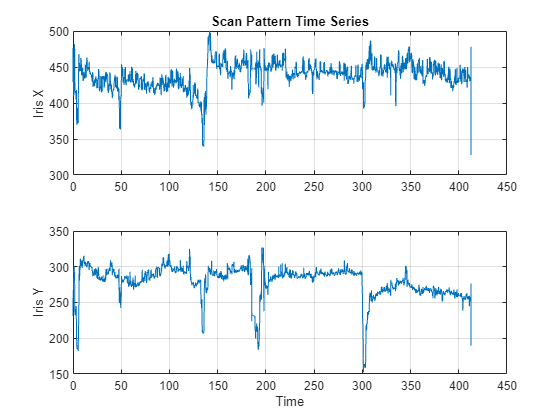

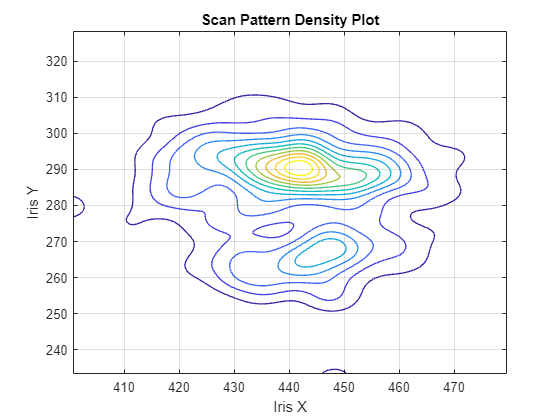

plotIrisFeatures(irisResult,time,desireFs, 5);

### Exceedance Data Analysis

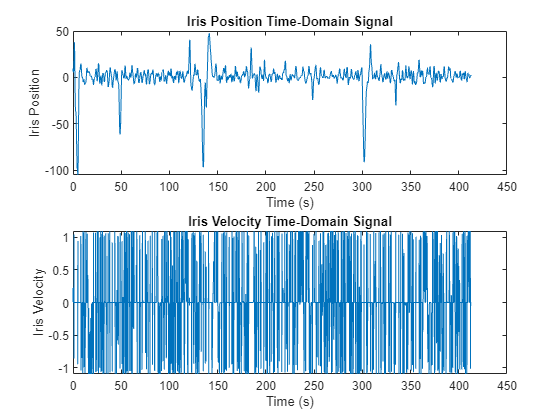

Feature values for a single trial:

Iris Position:
mean: 0.0000
std: 13.9540
skewness: -3.6809
kurtosis: 24.9893
rms: 13.9534
crestFactor: 3.4002
shapeFactor: 2.0439
impulseFactor: 15.3616
zeroCrossingRate: 0.0170
autocorrelation: -0.0000
avgPeakAmplitude: 6.5195
avgTimeToZero: 2.2705
numPeaks: 182.0000
spectralCentroid: 0.0894
spectralBandwidth: 0.0910
spectralContrast: 49608546167641.9766
waveletFeatures.energy: 145702.8818
waveletFeatures.entropy: -198634639.3071
waveletFeatures.meanCoeff: 0.0000
waveletFeatures.stdCoeff: 2.4493
numFixation: 169.0000
meanFixationDuration: 169.0000
stdFixationDuration: 0.0000
fixation_durations: 7.5000
8.333333e-01: 3.2667
1.833333e+00: 7.4333
1.533333e+00: 1.1000
2.600000e+00: 1.5000
9.666667e-01: 2.5333
1.000000e+00: 2.7667
1.500000e+00: 2.5333
1.100000e+00: 1.4333
1.233333e+00: 3.4667
5.900000e+00: 5.3333
□: 4.0333
1.166667e+00: 1.7000
1.766667e+00: 1.7000
1.800000e+00: 2.9667
2.866667e+00: 1.8667
□: 1.9333
4.200000e+00: 1.0333
1.433333e+00: 2.033

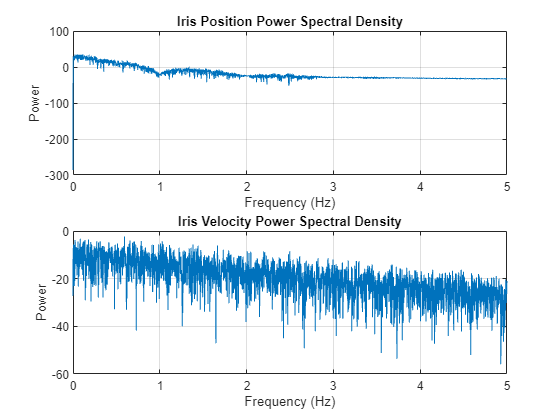

%exceedance

output.info.refIas = 90;

refIas= output.info.refIas;

 hdev = data.hdev;
 vdev = data.vdev;
 iasdev = (data.ias - refIas); 
DME = data.dmeNM;

exceedance = exceedance_analysis(hdev, vdev, iasdev, DME, time, desireFs);

[startTimes, durations, amplitudes] = findExceedingPeaks(exceedance.rateExceedance, ...
    time);
    exceedance.exceedingStartTimes = startTimes;
    exceedance.exceedingDurations = durations;
    exceedance.exceedingAmplitudes =amplitudes;



%display the features for exceedance in plots
maxFreqInChart = 2;
plotExceedanceFeatures(exceedance, time, desireFs,maxFreqInChart);




### Average the post and pre CAT results:

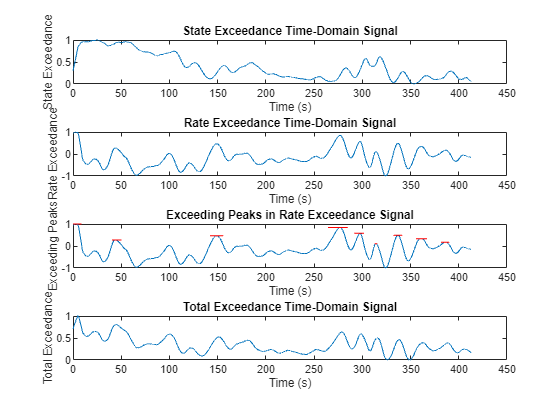

Feature values for a single trial:

State Exceedance:
mean: 0.3999
std: 0.2952
skewness: 0.7030
kurtosis: 2.1729
rms: 0.4970
crestFactor: 2.0119
shapeFactor: 1.2430
impulseFactor: 2.5007
zeroCrossingRate: 0.0002
autocorrelation: 8016.4823
avgPeakAmplitude: 0.5430
avgTimeToZero: 16.5181
numPeaks: 25.0000
spectralCentroid: 0.0388
spectralBandwidth: 0.0446
spectralContrast: 33401928028.1032
waveletFeatures.energy: 10.5061
waveletFeatures.entropy: -4191.3235
waveletFeatures.meanCoeff: 0.0000
waveletFeatures.stdCoeff: 0.0161

Rate Exceedance:
mean: 0.3082
std: 0.2639
skewness: 1.0313
kurtosis: 3.2874
rms: 0.4057
crestFactor: 2.4649
shapeFactor: 1.3164
impulseFactor: 3.2448
zeroCrossingRate: 0.0000
autocorrelation: 1969.0195
avgPeakAmplitude: 0.3930
avgTimeToZero: 10.6133
numPeaks: 11.0000
spectralCentroid: 0.0420
spectralBandwidth: 0.0475
spectralContrast: 584728340.4886
waveletFeatures.energy: 10.7796
waveletFeatures.entropy: -3731.7869
waveletFeatures.meanCoeff: 0.0000
waveletFeatures.std

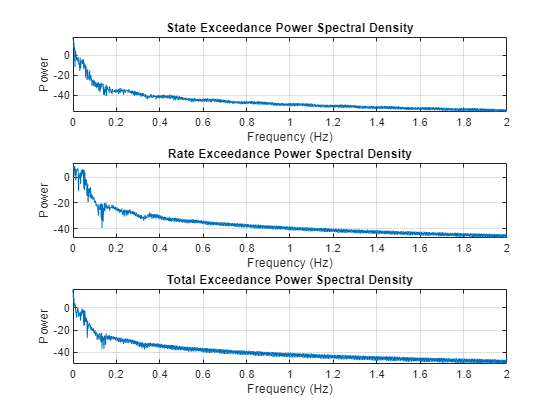

% Create an empty struct for the average data
avgCAT = struct();
beforeCAT = preFlightCAT;

afterCAT = postFlightCAT;
% Loop through each struct in the beforeCAT array
for i = 1:length(beforeCAT)
    % Loop through each field in the struct
    fields = fieldnames(beforeCAT(i));
    for j = 1:length(fields)
        % Skip the 'blocks' field
        if strcmp(fields{j},'blocks')
            continue
        end
        % If the field is a scalar or a string, copy it directly to the
        % avgCAT struct`
        if isscalar(beforeCAT(i).(fields{j})) || ischar(beforeCAT(i).(fields{j}))
            avgCAT(i).(fields{j}) = (beforeCAT(i).(fields{j}) + afterCAT(i).(fields{j}))/2;
        % If the field is a struct, loop through its fields and average each one
        elseif isstruct(beforeCAT(i).(fields{j}))
            subfields = fieldnames(beforeCAT(i).(fields{j}));
            substruct = struct();
            for k = 1:length(subfields)
                bef = beforeCAT(i).(fields{j}).(subfields{k});
                aft = afterCAT(i).(fields{j}).(subfields{k});
                substruct.(subfields{k}) = (bef+aft)/2 ;
            end
            avgCAT(i).(fields{j}) = substruct;
        % Otherwise, assume the field is an array and average its values element-wise
        else
            avgCAT(i).(fields{j}) = (beforeCAT(i).(fields{j}) + afterCAT(i).(fields{j}))/2;
        end
    end
end



### Output Object Data

%output object definiton
pilot.data = data;
output.trial = pilot;
output.trial_raw = pilot_raw;
output.preFlightCAT = preFlightCAT;
output.postFlightCAT = postFlightCAT;
output.avgFlightCAT = avgCAT;
output.irisResult = irisResult;
output.exceedance = exceedance;
output.info.stepTime = step_window;
output.info.windowTime = window;
output.info.sampleRate = desireFs;


%store log folder Name and trialLogs file name


% Assuming 'output' is your struct
pilotName = output.trial.name;
timeStr = output.trial.time;

% Replace any ' ' with '_' in pilotName
pilotName = strrep(pilotName, ' ', '_');
pilotName = strrep(pilotName, '-', '_');

% Replace any ':' with '_' to avoid issues with file paths
timeStr = strrep(timeStr, ':', '_');
timeStr = strrep(timeStr, ' ', '_');
timeStr = strrep(timeStr, '-', '_');

% Create the variable and file name
pilotName_time = sprintf('%s_%s', pilotName, timeStr);

output.info.pilotName_time = pilotName_time;
output.info.logFolder = last_folder_name;

 save (tempMatPath,'output')

%show output data structure
disp("Trial Data Structure")

Trial Data Structure


display_struct(output);

info: (struct)
  refIas: (double)
  stepTime: (double)
  windowTime: (double)
  sampleRate: (double)
  pilotName_time: (char)
  logFolder: (char)
trial: (struct)
  name: (char)
  rating: (char)
  beginPVT: (double)
  endPVT: (double)
  hoursAwake: (double)
  selfRating: (double)
  taskTitle: (char)
  data: (struct)
    irisx: (double)
    irisy: (double)
    dxIris: (double)
    dyIris: (double)
    aileron: (double)
    elevator: (double)
    throttle: (double)
    rudder: (double)
    roll: (double)
    pitch: (double)
    hdev: (double)
    vdev: (double)
    dmeNM: (double)
    ias: (double)
    altitude: (double)
    vvi: (double)
    heading: (double)
    rpm: (double)
    latitude: (double)
    longitude: (double)
    time: (double)
  description: (cell)
  time: (string)
  caffein: (char)
trial_raw: (struct)
  name: (char)
  rating: (char)
  beginPVT: (double)
  endPVT: (double)
  hoursAwake: (double)
  selfRating: (double)
  taskTitle: (char)
  data: (table)
  description: (cel

### Save Scalograms

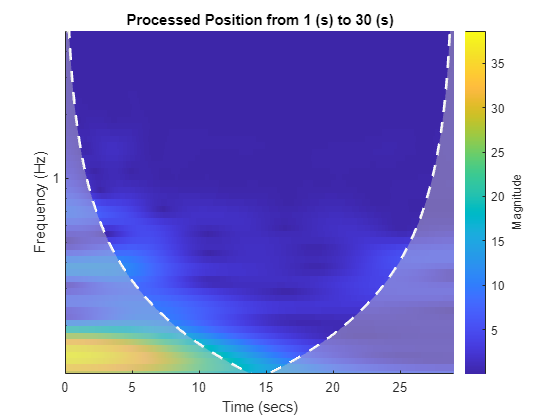

Mean Rate Exceedance = -0.043286




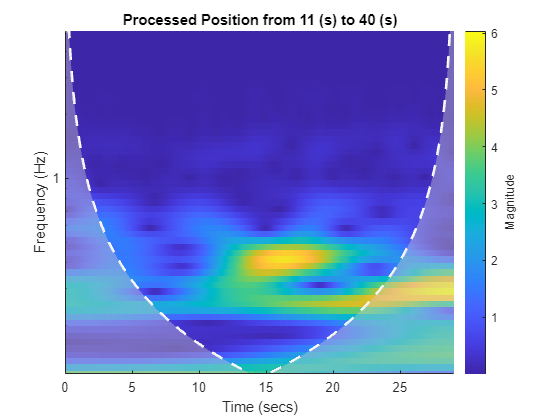

Mean Rate Exceedance = -0.41826




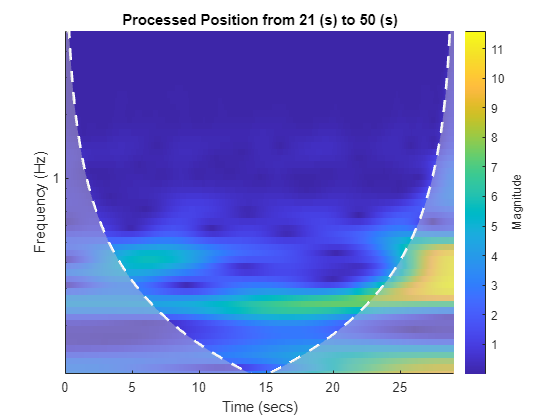

Mean Rate Exceedance = -0.21776




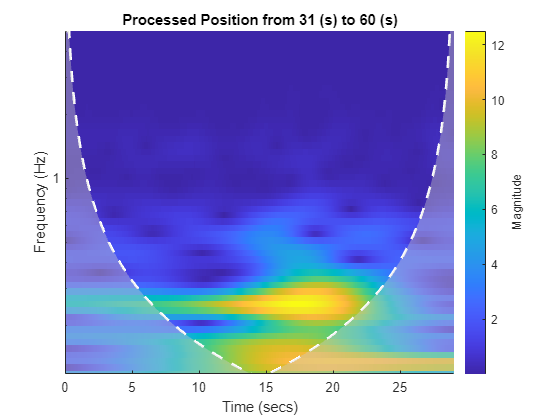

Mean Rate Exceedance = -0.16261




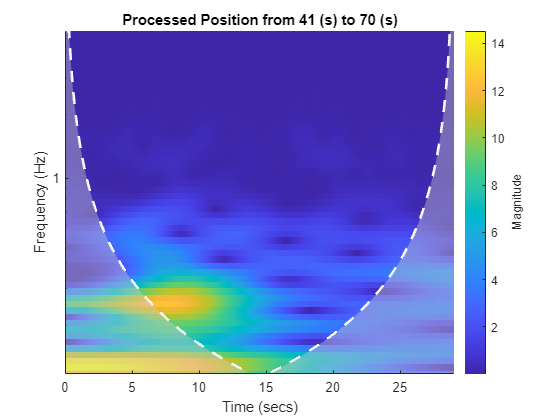

Mean Rate Exceedance = -0.31194




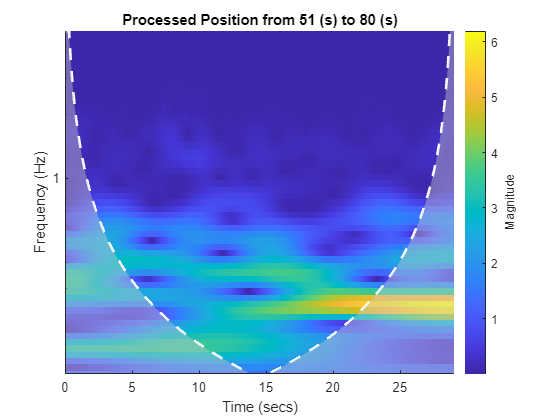

Mean Rate Exceedance = -0.60637




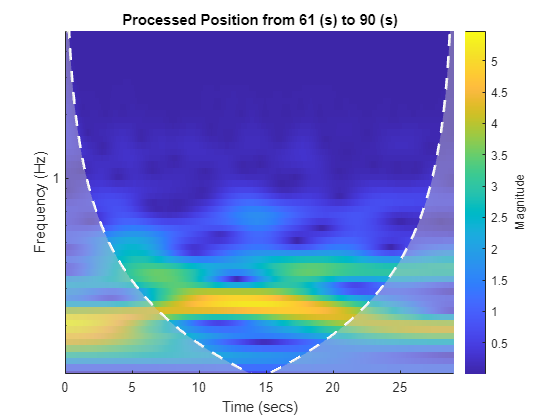

Mean Rate Exceedance = -0.69339




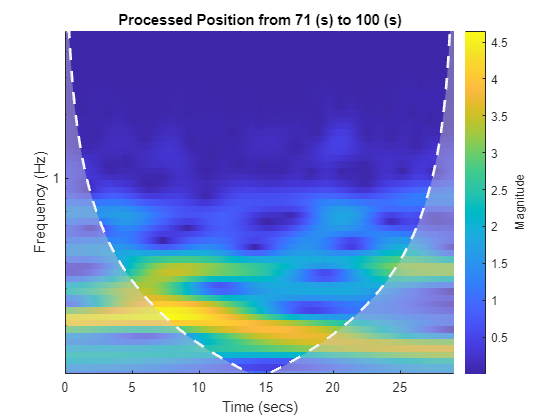

Mean Rate Exceedance = -0.45329




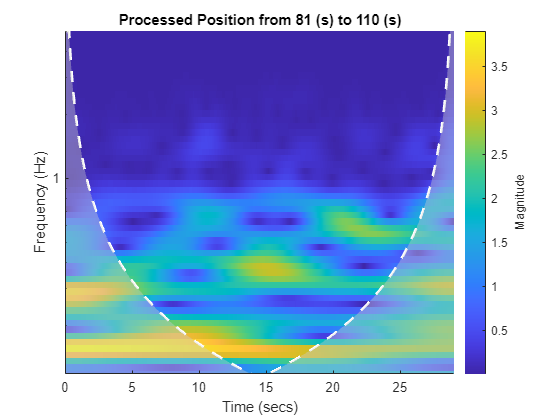

Mean Rate Exceedance = -0.34188




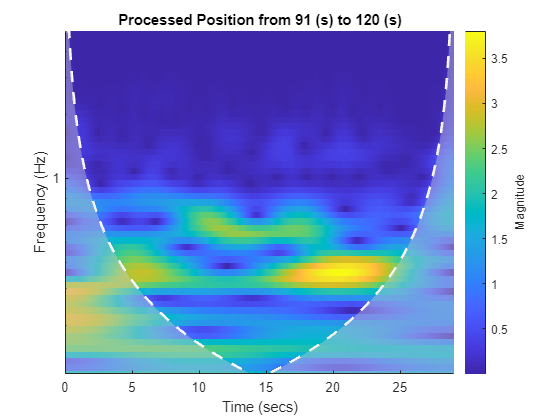

Mean Rate Exceedance = -0.3941




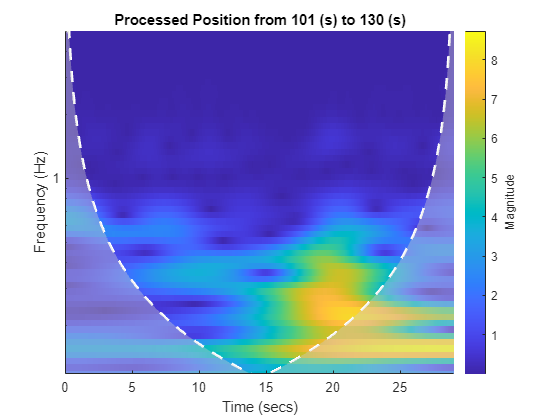

Mean Rate Exceedance = -0.542




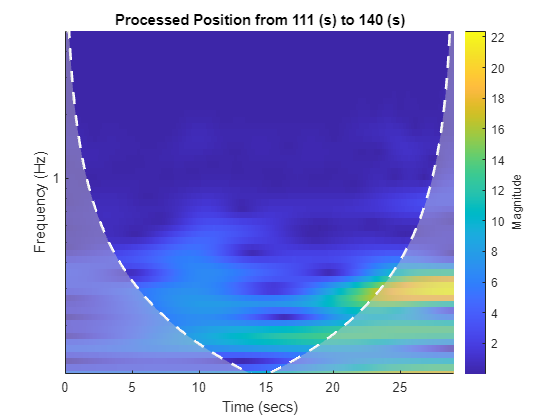

Mean Rate Exceedance = -0.60327




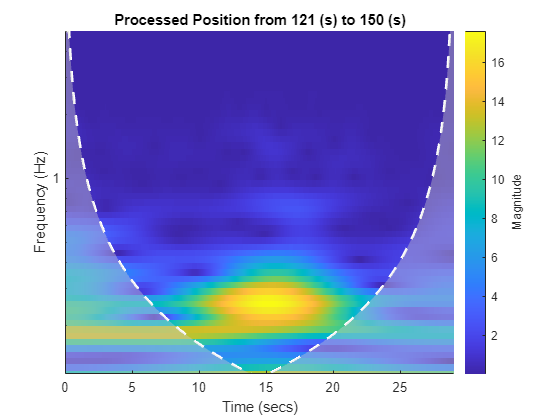

Mean Rate Exceedance = -0.29374




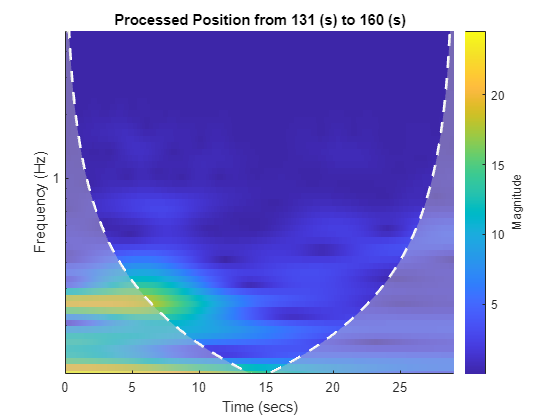

Mean Rate Exceedance = -0.046919




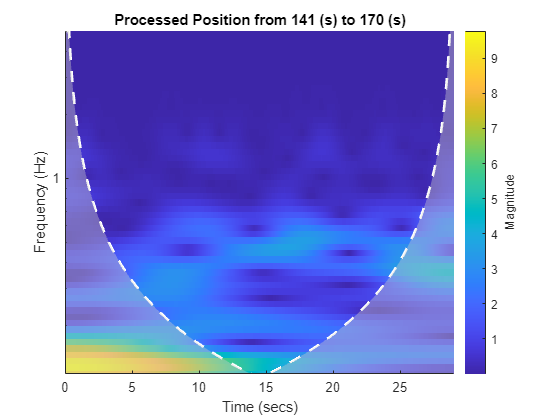

Mean Rate Exceedance = 0.06696




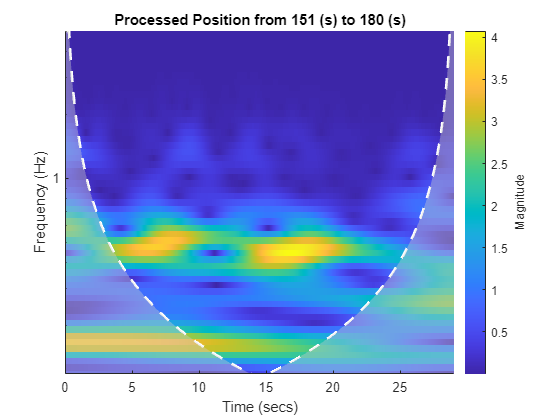

Mean Rate Exceedance = -0.039451




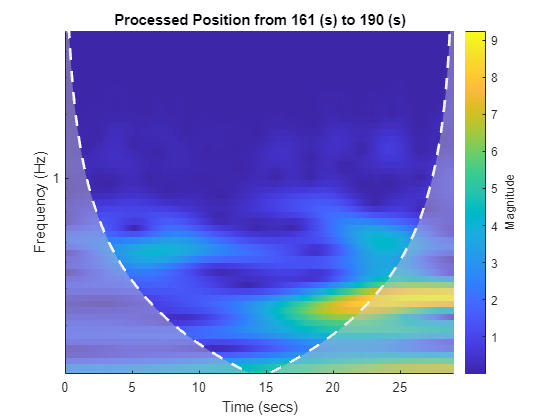

Mean Rate Exceedance = -0.111




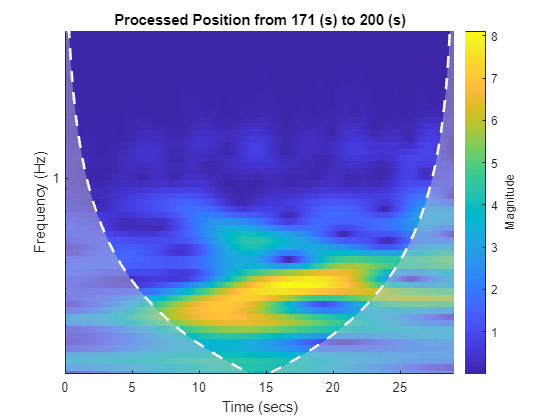

Mean Rate Exceedance = -0.21046




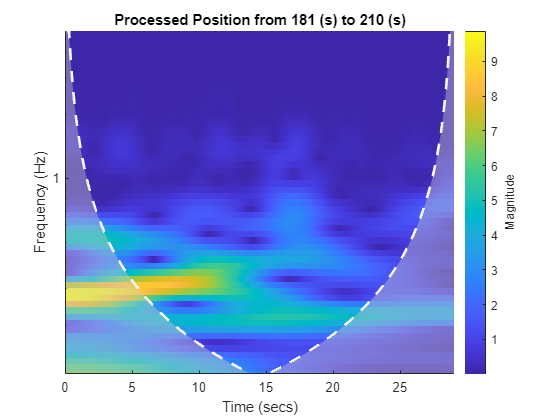

Mean Rate Exceedance = -0.30342




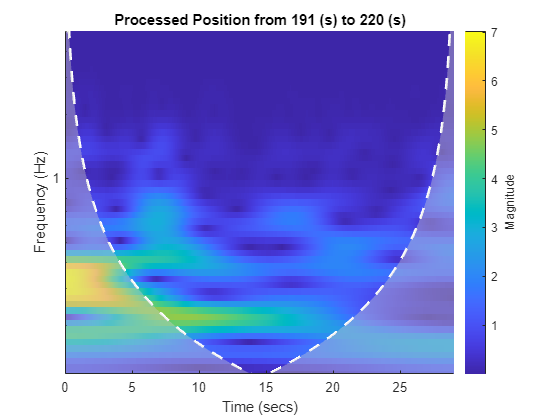

Mean Rate Exceedance = -0.34154




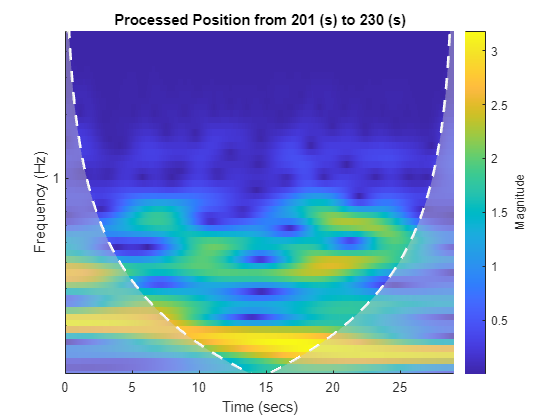

Mean Rate Exceedance = -0.26839




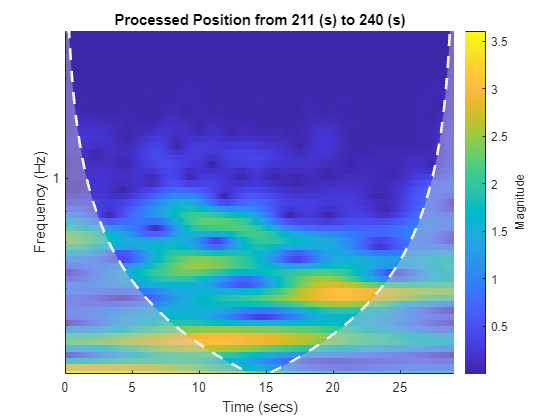

Mean Rate Exceedance = -0.2838




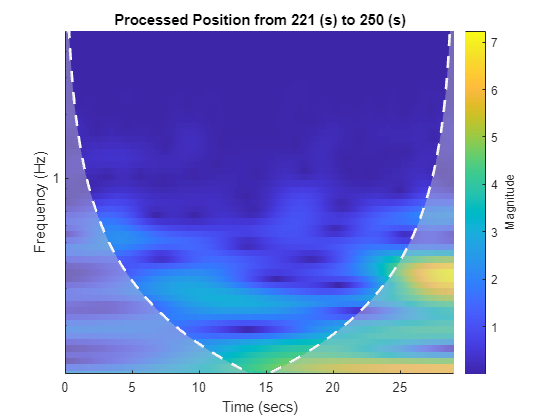

Mean Rate Exceedance = -0.26212




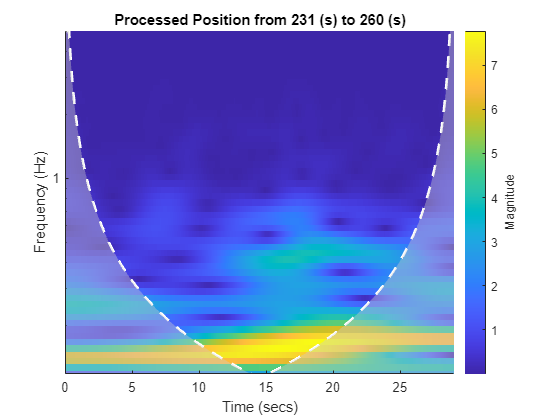

Mean Rate Exceedance = -0.23947




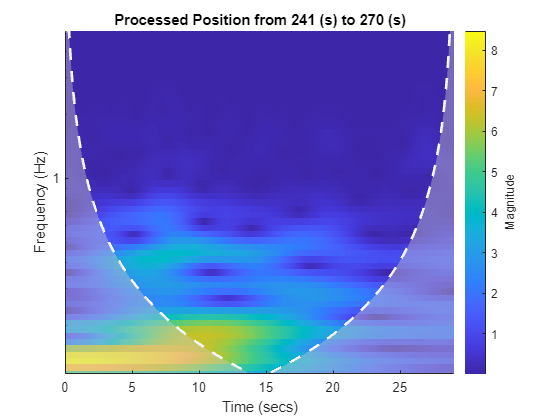

Mean Rate Exceedance = -0.093061




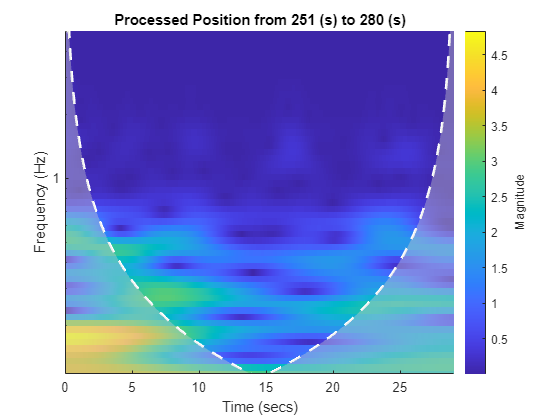

Mean Rate Exceedance = 0.23689




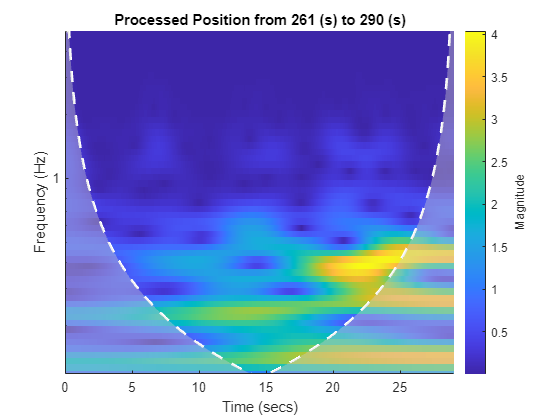

Mean Rate Exceedance = 0.33097




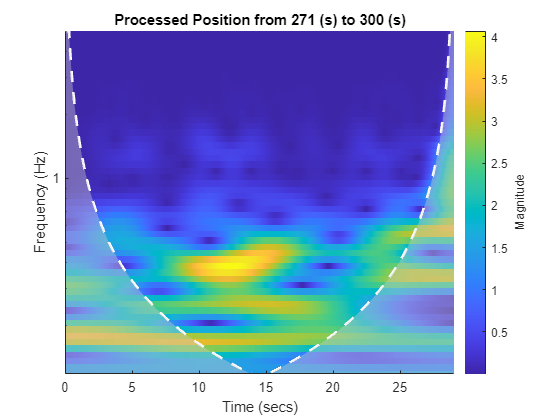

Mean Rate Exceedance = 0.38537




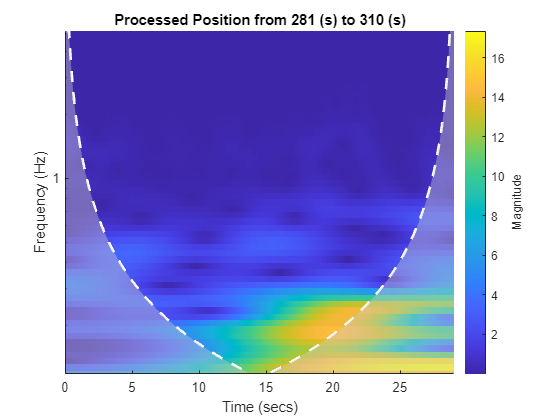

Mean Rate Exceedance = 0.024571




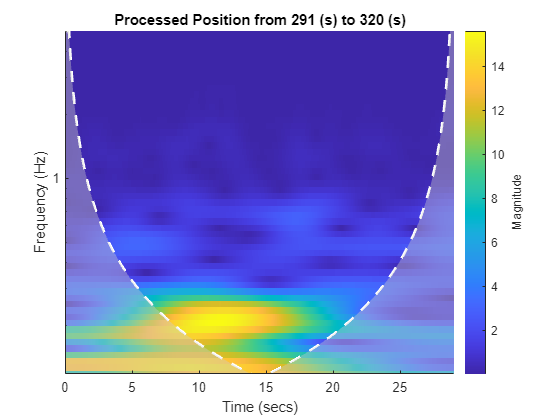

Mean Rate Exceedance = -0.033083




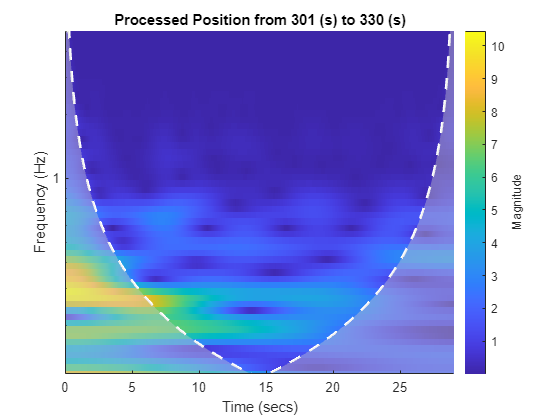

Mean Rate Exceedance = -0.42723




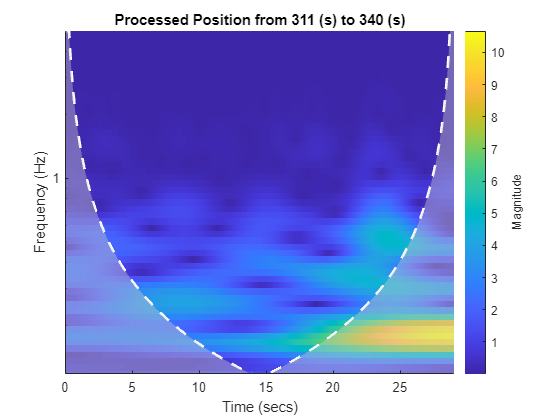

Mean Rate Exceedance = -0.21718




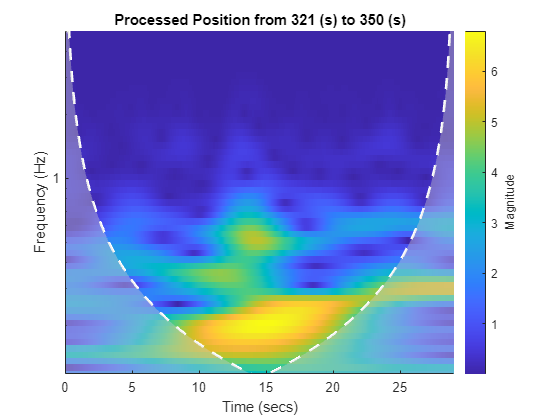

Mean Rate Exceedance = -0.29725




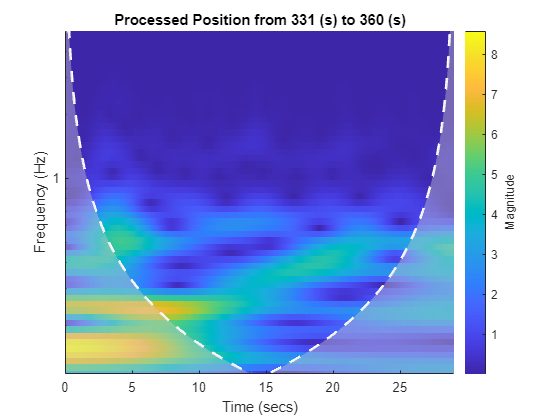

Mean Rate Exceedance = -0.057318




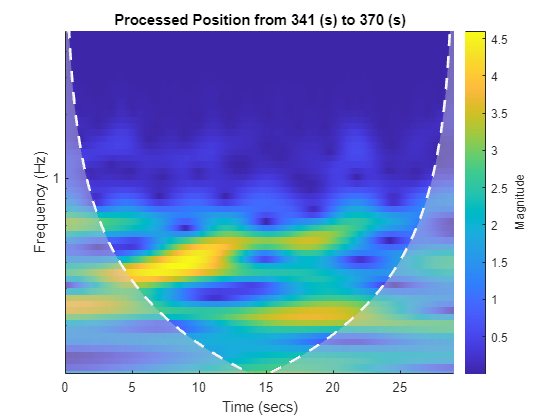

Mean Rate Exceedance = -0.099411




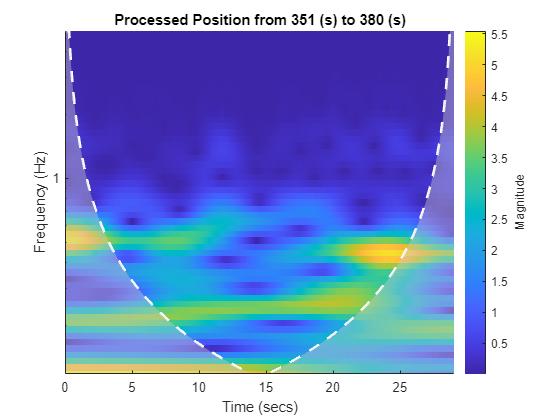

Mean Rate Exceedance = 0.026494




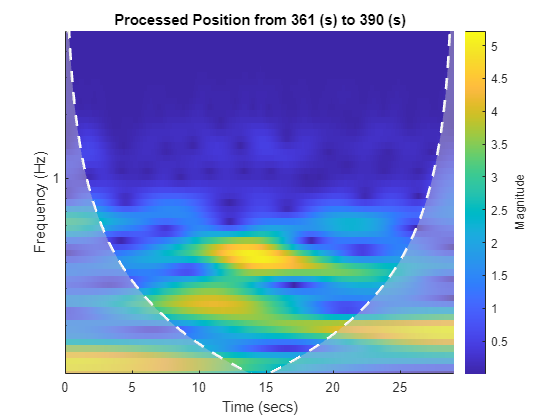

Mean Rate Exceedance = 0.056406




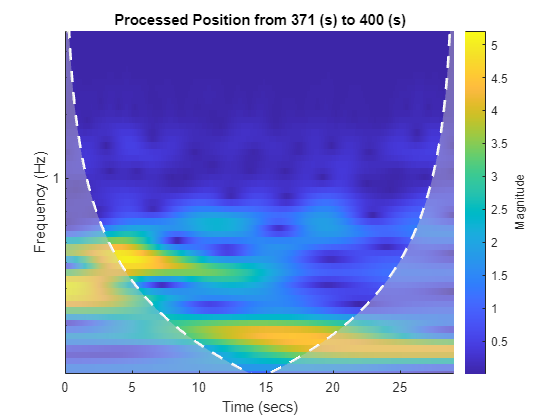

Mean Rate Exceedance = -0.059886




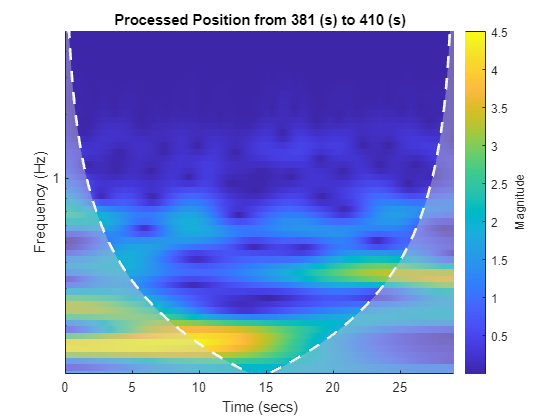

Mean Rate Exceedance = -0.069799




% Add this line at the beginning
scalogramDataSource = 1; % Can be 1, 2, 3, or 4

% Modify the scalogram data selection part
% Choose which data to use for building the scalogram
switch scalogramDataSource
    case 1
        data = irisResult.processedPosition;
        data_label = 'Processed Position';
    case 2
        data = irisResult.positionDetrended;
        data_label = 'Detrended Position';
    case 3
        data = irisResult.raw_position;
        data_label = 'Raw Position';
    case 4
        data = irisResult.processed_velocity;
        data_label = 'Processed Velocity';
    otherwise
        error('Invalid value for scalogramDataSource. It should be between 1 and 4.');
end

% Combine the loops
create_scalogram_combined = true;
remove_existing_scalograms_combined = true;

if create_scalogram_combined
     % Create directories if they do not exist
    if ~isfolder(dirPath + "/irisScalogram")
        mkdir(dirPath + "/irisScalogram");
    end
    if ~isfolder(dirPath + "/irisScalogramWithExc")
        mkdir(dirPath + "/irisScalogramWithExc");
    end
    if ~isfolder(dirPath + "/irisScalogramBinary")
        mkdir(dirPath + "/irisScalogramBinary");
    end
    if ~isfolder(dirPath + "/irisScalogramBinary/0")
        mkdir(dirPath + "/irisScalogramBinary/0");
    end
    if ~isfolder(dirPath + "/irisScalogramBinary/1")
        mkdir(dirPath + "/irisScalogramBinary/1");
    end

    % Remove existing files if necessary
    if remove_existing_scalograms_combined
        delete(dirPath + "/irisScalogram/*.jpg");
        delete(dirPath + "/irisScalogramWithExc/*.jpg");
        delete(dirPath + "/irisScalogramBinary/0/*.jpg");
        delete(dirPath + "/irisScalogramBinary/1/*.jpg");
    end

    excGradNormalize = exceedance.rateExceedance;

    for i = 1:step_window:max(time) - window
    start_time = i;
    end_time = i + window - 1;

    start_index = find(time == start_time);
    end_index = find(time == end_time);
% Build the scalogram
    fig = figure;
    buildScalogram(data, time, [start_time, end_time]);
    main_title = data_label + " from " + string(start_time) + " (s) to " + string(end_time) + " (s)";
    title(main_title);

    % Add subtitle
    meanCurExc = mean(exceedance.rateExceedance(start_index:end_index)) ;
    subtitle = "Mean Rate Exceedance = " + string(meanCurExc);


    % Save scalogram
    f = getframe;
    imwrite(f.cdata, dirPath + "/irisScalogram/" + string(start_time) + "_" + string(end_time) + ".jpg");

    % Save scalogram with exceedance
    imwrite(f.cdata, dirPath + "/irisScalogramWithExc/" + string(int16(meanCurExc)) + ".jpg");

    % Save binary scalogram
    meanCurExcGradient = mean(excGradNormalize(start_index:end_index));
    if (meanCurExcGradient <= excGradTreshhold)
        alertState = 1;
        imwrite(f.cdata, dirPath + "/irisScalogramBinary/1/" + string(int16(meanCurExcGradient )) + ".jpg");
    else
        alertState = 0;
        imwrite(f.cdata, dirPath + "/irisScalogramBinary/0/" + string(int16(meanCurExcGradient )) + ".jpg");
    end
 disp(subtitle+newline+newline);
    pause(0.1); % Add a short pause here
end

end

Export te results and reports in to a PDF


%  export("autoExperimentAnalyzerV2.mlx",dirPath+"\"+pilotName_time,run=false,HideCode=true,PageSize="A4");






if(batchMode==true)
    clear;
end

